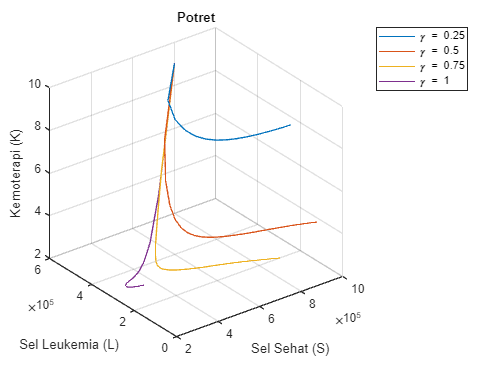

clc; clear all; clear output;
Gamma = [0.25, 0.5, 0.75, 1];

for i = 1:length(Gamma)
    r_1 = 0.18; % laju pertumbuhan sel leukemia /hari
    r_2 = 0.4;
    c = 1.2e-6;
    b = 1e-6;
    beta = 1e-6;
    alpha_1 = 0.05;
    alpha_2 = 0.01;
    gamma = Gamma(i);
    mu = 2.5;
    
    f = @(t, L, S, K) r_1.*L.*(1-c.*L)-alpha_1.*K.*L;
    g = @(t, L, S, K) r_2.*S.*(1-b.*S)-beta.*S.*L-alpha_2.*K.*S;
    q = @(t, L, S, K) mu-gamma.*K; 
    
    dL = f;
    dS = g;
    dK = q;
    t0 = 0;
    tN = 300;
    Nt = 300;
    l0 = 5e5;
    s0 = 7e5;
    k0 = 10;

    [t(i, :), L(i, :), S(i, :), K(i, :)] = runge_kutta(t0,tN,Nt,l0,s0,k0,f,g,q);
end
figure;
for i = 1:4
    plot3(S(i, :), L(i, :), K(i, :), "DisplayName", "\gamma = " + string(Gamma(i)));
    hold on
end
hold off
xlabel('Sel Sehat (S)');
ylabel('Sel Leukemia (L)');
zlabel('Kemoterapi (K)');
title('Potret');
grid on;
legend

K

K =    10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000
   10.0000    8.0339    6.8409    6.1170    5.6777    5.4112    5.2495    5.1514    5.0919    5.0557    5.0338    5.0205    5.0125    5.0076    5.0046    5.0028    5.0017    5.0010    5.0006    5.0004    5.0002    5.0001    5.0001    5.0001    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5

L

L = 1.0e+05 *

    5.0000    3.3241    2.2743    1.5850    1.1182    0.7956    0.5694    0.4092    0.2949    0.2130    0.1541    0.1116    0.0808    0.0586    0.0425    0.0309    0.0224    0.0163    0.0118    0.0086    0.0062    0.0045    0.0033    0.0024    0.0017    0.0013    0.0009    0.0007    0.0005    0.0003    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    5.0000    3.4998    2.7103    2.2293    1.9028    1.6624    1.4745    1.3209    1.1916    1.0802    0.9829    0.8968    0.8202    0.7515    0.6897    0.6338    0.5832    0.5372    0.4953    0.4571    0.4222    0.3902    0.3609    0.3339    0.3092    0.2865    0.2655    0.2462    0.2284    0.2119    0.1967    0.1827    0.1697    0.1577    0.1465    0.1362    0.1266    0.1178    0.1095    0.1019    0.0948    0.0882    0.0821    0.0764    0.0711    0.0662    0.0617    0.0574    

S

S = 1.0e+05 *

    7.0000    4.9688    4.2424    4.0165    4.0399    4.2077    4.4644    4.7733    5.1070    5.4434    5.7659    6.0626    6.3262    6.5540    6.7459    6.9046    7.0336    7.1370    7.2190    7.2834    7.3337    7.3727    7.4028    7.4260    7.4437    7.4573    7.4676    7.4755    7.4815    7.4860    7.4894    7.4920    7.4940    7.4955    7.4966    7.4974    7.4981    7.4986    7.4989    7.4992    7.4994    7.4995    7.4997    7.4997    7.4998    7.4999    7.4999    7.4999    7.4999    7.5000
    7.0000    4.9855    4.2358    3.9405    3.8626    3.9087    4.0343    4.2144    4.4328    4.6773    4.9380    5.2066    5.4757    5.7395    5.9931    6.2331    6.4571    6.6639    6.8531    7.0251    7.1806    7.3207    7.4468    7.5601    7.6620    7.7536    7.8362    7.9107    7.9781    8.0392    8.0947    8.1452    8.1914    8.2335    8.2721    8.3075    8.3400    8.3699    8.3975    8.4229    8.4463    8.4680    8.4880    8.5066    8.5237    8.5396    8.5544    8.5680    

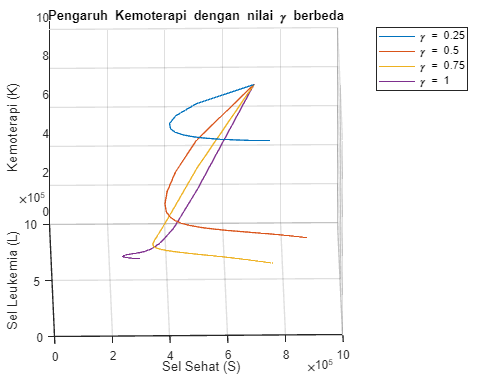

% Membuat plot 3D awal
figure;
for i = 1:4
    plot3(S(i, :), L(i, :), K(i, :), "DisplayName", "\gamma = " + string(Gamma(i)));
    hold on
end
hold off
xlabel('Sel Sehat (S)');
ylabel('Sel Leukemia (L)');
zlabel('Kemoterapi (K)');
xlim([0, 10e5])
ylim([0, 10e5])
zlim([0, 10])
title('Pengaruh Kemoterapi dengan nilai \gamma berbeda');
grid on;
legend


% Inisialisasi video
writerObj = VideoWriter('Plotting Pengaruh Gamma.mp4', 'MPEG-4');
writerObj.FrameRate = 30; % Frame rate video (frame per detik)
open(writerObj);

% Mengatur sudut pandang dan membuat video
for angle = 0:1:359
    view(angle, 30); % Mengatur sudut pandang (azimuth, elevation)
    drawnow;

    % Mengambil frame
    frame = getframe(gcf);
    writeVideo(writerObj, frame);
end


% Menutup video
close(writerObj);


clc; clear all; clear output;
MU = [1, 2.5, 4, 6];

for i = 1:length(MU)
    r_1 = 0.18; % laju pertumbuhan sel leukemia /hari
    r_2 = 0.4;
    c = 1.2e-6;
    b = 1e-6;
    beta = 1e-6;
    alpha_1 = 0.05;
    alpha_2 = 0.01;
    gamma = 1;
    mu = MU(i);
    
    f = @(t, L, S, K) r_1.*L.*(1-c.*L)-alpha_1.*K.*L;
    g = @(t, L, S, K) r_2.*S.*(1-b.*S)-beta.*S.*L-alpha_2.*K.*S;
    q = @(t, L, S, K) mu-gamma.*K; 
    
    dL = f;
    dS = g;
    dK = q;
    t0 = 0;
    tN = 300;
    Nt = 300;
    l0 = 5e5;
    s0 = 7e5;
    k0 = 10;

    [t(i, :), L(i, :), S(i, :), K(i, :)] = runge_kutta(t0,tN,Nt,l0,s0,k0,f,g,q);
end

% Plot hasil

K

K =    10.0000    4.3750    2.2656    1.4746    1.1780    1.0667    1.0250    1.0094    1.0035    1.0013    1.0005    1.0002    1.0001    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   10.0000    5.3125    3.5547    2.8955    2.6483    2.5556    2.5209    2.5078    2.5029    2.5011    2.5004    2.5002    2.5001    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2

L

L = 1.0e+05 *

    5.0000    3.8954    3.6796    3.7195    3.8464    4.0022    4.1644    4.3237    4.4762    4.6200    4.7545    4.8794    4.9946    5.1004    5.1970    5.2849    5.3647    5.4367    5.5015    5.5597    5.6119    5.6585    5.7000    5.7370    5.7699    5.7991    5.8250    5.8479    5.8682    5.8861    5.9020    5.9159    5.9282    5.9391    5.9487    5.9571    5.9645    5.9711    5.9768    5.9819    5.9863    5.9902    5.9936    5.9967    5.9993    6.0017    6.0037    6.0055    6.0071    6.0085
    5.0000    3.7960    3.3997    3.2358    3.1520    3.0985    3.0579    3.0234    2.9927    2.9646    2.9387    2.9146    2.8922    2.8714    2.8519    2.8337    2.8167    2.8007    2.7858    2.7719    2.7588    2.7465    2.7350    2.7242    2.7141    2.7045    2.6956    2.6871    2.6792    2.6717    2.6647    2.6581    2.6519    2.6460    2.6405    2.6353    2.6303    2.6257    2.6213    2.6172    2.6133    2.6096    2.6062    2.6029    2.5998    2.5969    2.5941    2.5915    

S

S = 1.0e+05 *

    7.0000    5.0206    4.1620    3.6136    3.1844    2.8153    2.4854    2.1869    1.9163    1.6717    1.4515    1.2546    1.0794    0.9246    0.7885    0.6698    0.5666    0.4776    0.4011    0.3358    0.2802    0.2332    0.1935    0.1602    0.1323    0.1090    0.0897    0.0737    0.0604    0.0495    0.0404    0.0330    0.0270    0.0220    0.0179    0.0146    0.0118    0.0096    0.0078    0.0064    0.0052    0.0042    0.0034    0.0028    0.0022    0.0018    0.0015    0.0012    0.0010    0.0008
    7.0000    5.0128    4.1842    3.7137    3.3999    3.1717    2.9980    2.8625    2.7554    2.6705    2.6030    2.5498    2.5082    2.4762    2.4523    2.4352    2.4239    2.4174    2.4151    2.4163    2.4205    2.4273    2.4362    2.4469    2.4591    2.4725    2.4870    2.5021    2.5179    2.5341    2.5506    2.5673    2.5839    2.6006    2.6171    2.6334    2.6494    2.6651    2.6804    2.6954    2.7099    2.7240    2.7376    2.7507    2.7633    2.7755    2.7872    2.7984    

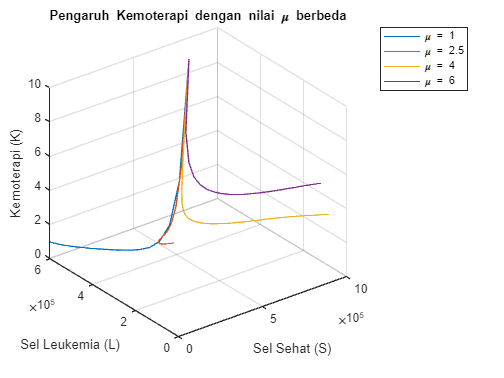

figure;
for i = 1:4
    plot3(S(i, :), L(i, :), K(i, :), "DisplayName", "\mu = " + string(MU(i)));
    hold on
end
hold off
xlabel('Sel Sehat (S)');
ylabel('Sel Leukemia (L)');
zlabel('Kemoterapi (K)');
title('Pengaruh Kemoterapi dengan nilai \mu berbeda');
legend
grid on;

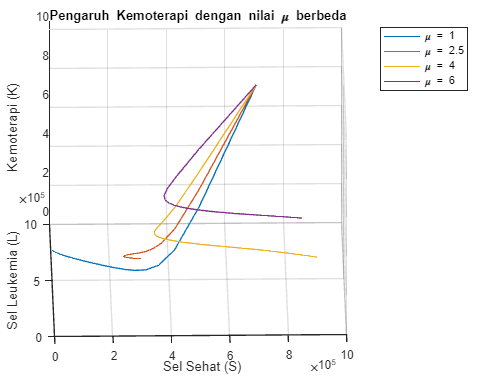


% Membuat plot 3D awal
figure;
for i = 1:4
    plot3(S(i, :), L(i, :), K(i, :), "DisplayName", "\mu = " + string(MU(i)));
    hold on
end
hold off
xlabel('Sel Sehat (S)');
ylabel('Sel Leukemia (L)');
zlabel('Kemoterapi (K)');
xlim([0, 10e5])
ylim([0, 10e5])
zlim([0, 10])

title('Pengaruh Kemoterapi dengan nilai \mu berbeda');
grid on;
legend


% Inisialisasi video
writerObj = VideoWriter('Plotting Pengaruh Mu.mp4', 'MPEG-4');
writerObj.FrameRate = 30; % Frame rate video (frame per detik)
open(writerObj);

% Mengatur sudut pandang dan membuat video
for angle = 0:1:359
    view(angle, 30); % Mengatur sudut pandang (azimuth, elevation)
    drawnow;

    % Mengambil frame
    frame = getframe(gcf);
    writeVideo(writerObj, frame);
end


% Menutup video
close(writerObj);